# ANN

close all;clear;clc;
rng('default')
addpath models\
addpath utils\
load("data/data_rat010_0615_spike_train_selected.mat")
% load("data\simu.mat")
% mPFCspike=input';
% M1spike=output';

## hyper params

0/500...L=-116966.7957...mu=10...Lval=-38963.3628...DBRval10.1275


1/500...L=-54687.938...mu=0.1...Lval=-16925.535...DBRval3.2351


2/500...L=-50710.8625...mu=0.001...Lval=-15165.2533...DBRval1.3119


3/500...L=-50659.5673...mu=1e-05...Lval=-14979.2868...DBRval1.4938


4/500...L=-50597.0704...mu=1e-07...Lval=-14998.3379...DBRval1.3959


5/500...L=-50536.094...mu=1e-06...Lval=-14966.3919...DBRval1.3628


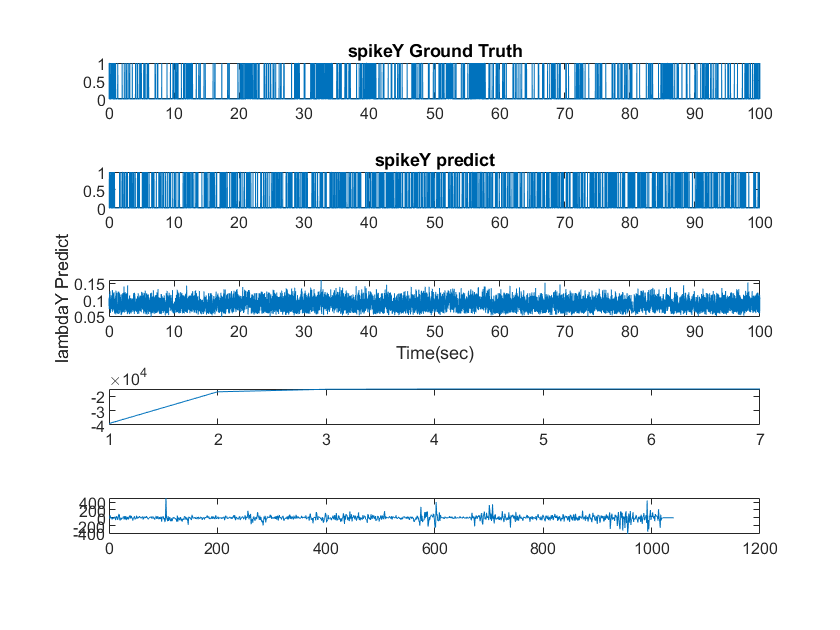

6/500...L=-50442.141...mu=0.01...Lval=-14966.5652...DBRval1.3215


preTrainN = 50; % initial multiple times to select better result
H = 10; % temporal history, todo: grid search
Nz = 20; % hidden neuron number, todo: grid search
xi1 = 0.05; % first stage weight parameters initial range param 
xi2 = 0.1; % second stage weight parameters initial range param
mu = 100; % modified LM algorithm param
thres = 1e-3; % stop error tolerance
iterThres = 7; % stop after error over threshold $ times
maxIter = 500; % max iteration num, over needs re-initial
alpha = 0; % Regulization parameter
M1Idx = 1; % select M1 neuron
splitFunc = @(history)splitData(mPFCspike,M1spike(:,M1Idx),history); % choose splitData function
verbose = 0;
W = runANN(H, Nz, xi1, xi2, mu, thres, iterThres, maxIter, alpha, splitFunc, verbose);